3.8

(a) define a1 b1 a2 b2

a1 = [1,-0.8];
b1 = [1];
a2 = [1,0.8];
b2 = [1];

(b) evaluate the frequency responses

[h1,omega1] = freqz(b1,a1,1024,'whole');
[h2,omega2] = freqz(b2,a2,1024,'whole');
subplot(2,1,1);
plot(omega1,abs(h1));
xlabel('omega');
ylabel('h1');
title('h1-omega1 figure');
subplot(2,1,2);
plot(omega2,abs(h2));
xlabel('omega');
ylabel('h2');
title('h2-omega2 figure');

(c)define vector a_x to be DTFS coefficients of x[n]. generate a plot

k = 0:19;
a_x = [0,3/4,zeros(1,7),-1/2,0,-1/2,zeros(1,7),3/4];
wk = (2*pi/20)*k;
stem(wk,a_x);
xlabel('wk');
ylabel('a_x');
legend('a_x');
title('a_x-k figure');

(d)define x_20 by ifft and a_x

n = -20:99;
x_20 = ifft(a_x)*20;
x = [x_20,x_20,x_20,x_20,x_20,x_20];
stem(n,x);
xlabel('n');
ylabel('x[n]');
title('x[n]-n figure');

(e) use filter to compute y1 and y2. input is x[n], system is system1 and system2.

y1 = filter(b1,a1,x);
y2 = filter(b2,a2,x);
subplot(2,1,1);
stem(n,y1);
xlabel('n');
ylabel('y1');
legend('y1');
title('y1[n] - n figure');
axis([0,99,-4,4]);
subplot(2,1,2);
stem(n,y2);
xlabel('n');
ylabel('y2');
legend('y2');
title('y2[n] - n figure');
axis([0,99,-4,4]);

(f)define y1_20, y2_20 to be segments. and compute a_y1, a_y2 using fft

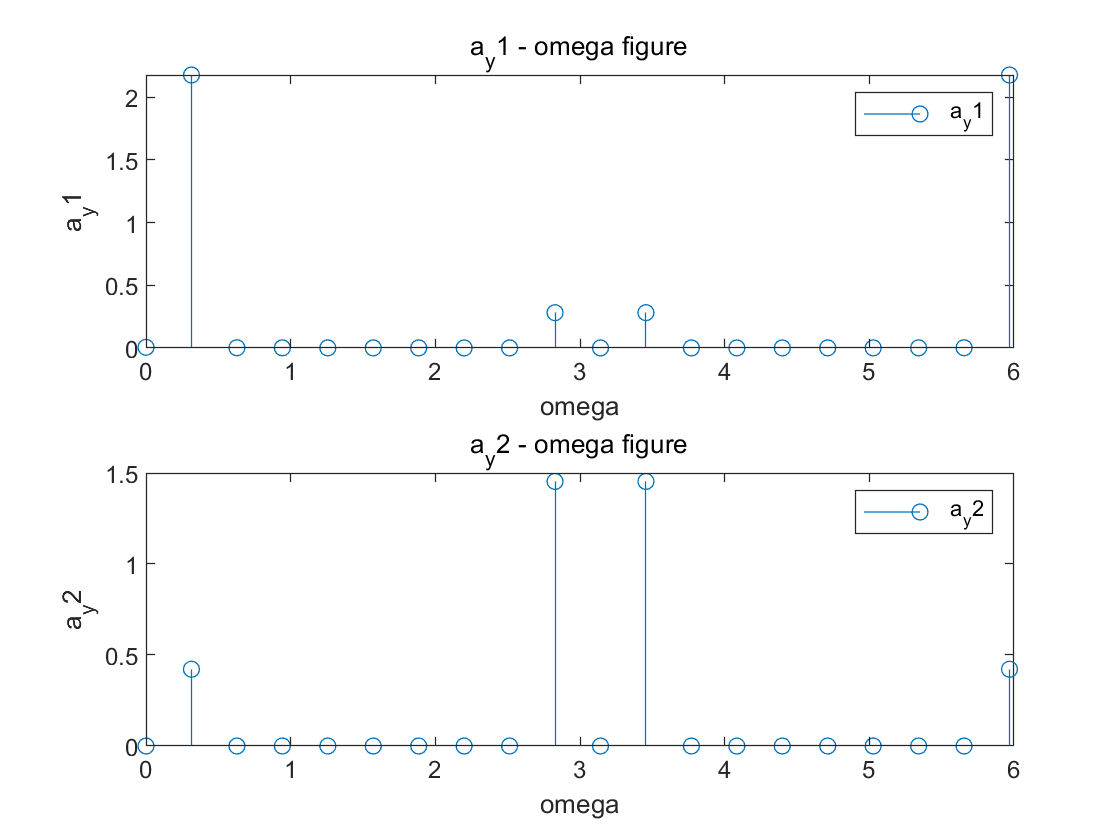

y1_20 = y1(21:40);
y2_20 = y2(41:60);
a_y1 = fft(y1_20)/20;
a_y2 = fft(y2_20)/20;
subplot(2,1,1);
stem(wk,abs(a_y1));
xlabel('omega');
ylabel('a_y1');
legend('a_y1');
title('a_y1 - omega figure');
subplot(2,1,2);
stem(wk,abs(a_y2));
xlabel('omega');
ylabel('a_y2');
legend('a_y2');
title('a_y2 - omega figure');